clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',8);
set(0,'DefaultTextFontsize',8);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

addpath("phaseportrait\");
figsize = [5,15,5,4];
figpos = [0.2 0.25 0.75 0.65];

m = 0.08;
l = 0.2;
g = 9.80665;

odefun = @(t,x)[x(2);-g/l*3/2*sin(x(1))];
plotpp(odefun,'tspan', 30,...
                      'plotQuiver', false,...
                      'linecolor', 0.5*[1,1,1], ...
                      'xlim', [-pi, 2*pi], 'ylim', [-25, 25]);

ans =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.1000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ] (1×105 double)
     Vertices: [105×2 double]

  Show all properties


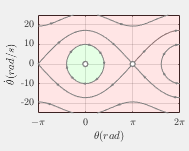



% load("v2_successful_reservoirs.mat");
% num = 2;
% theta = successful_runs{1,num}{1,1}(2,:);
% thetadot = successful_runs{1,num}{1,1}(3,:);
% thetaplan = successful_runs{1,num}{1,1}(4,:);
% thetaplandot = successful_runs{1,num}{1,1}(5,:);
% 
% hold on;
% plot(theta, thetadot);
% hold on;
% plot(thetaplan, thetaplandot);

set(gcf, 'unit', 'centimeters', 'position', figsize);
set(gcf, 'Visible','on');
set(gca, 'Position', figpos);
set(gca, 'color', [1 1 1],...
         'ticklabelinterpreter', 'latex',...
         'xtick', -pi:pi:2*pi,...
         'xticklabels', {'$$-\pi$$','$$0$$','$$\pi$$','$$2\pi$$'});
ylabel('$$\dot{\theta} (rad/s)$$', 'interpreter', 'latex');
xlabel('$$\theta (rad)$$', 'interpreter', 'latex');


% [~,h_legend] = legend('area1','area2');
% directly reachable
% 